# **PF**

## GLOBULOS BLANCOS

### a) Anotaciones

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\TF1N_1522'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.jpg'));

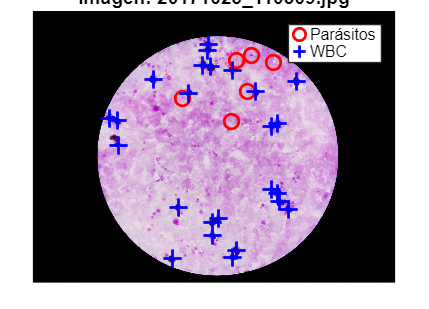

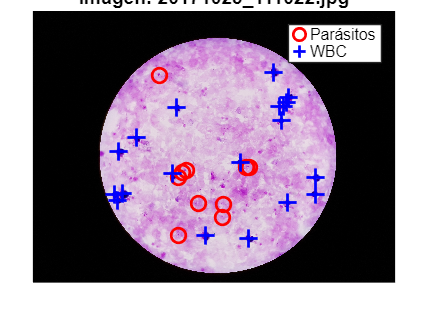

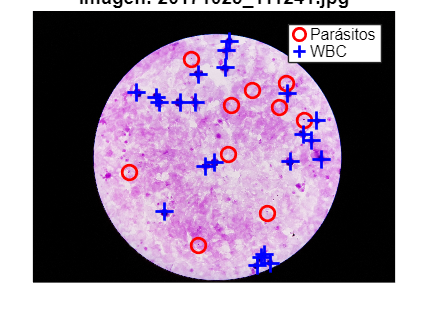

No se encontraron coordenadas de parásitos en la imagen: 20171023_111357.jpg


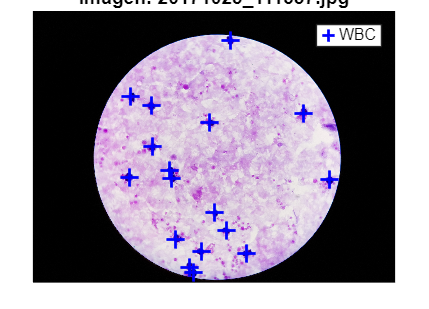

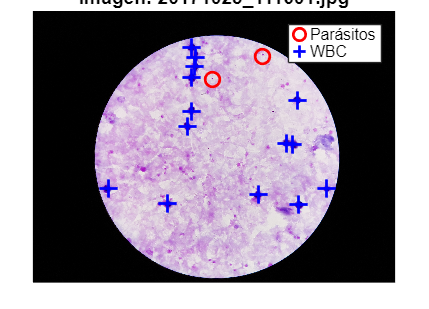

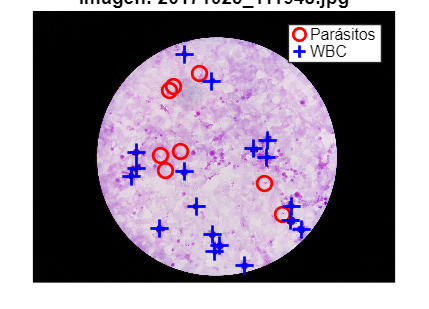

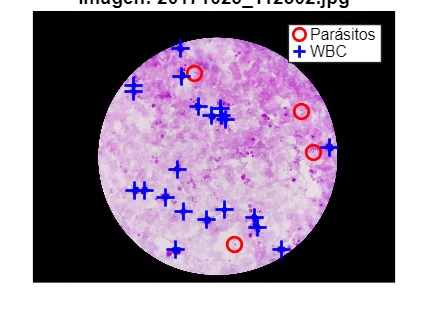

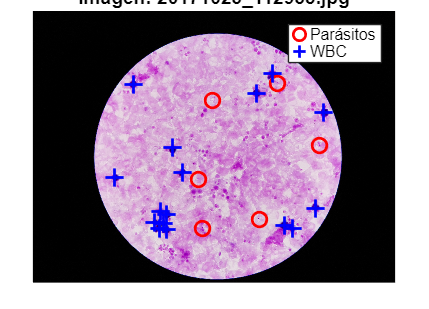

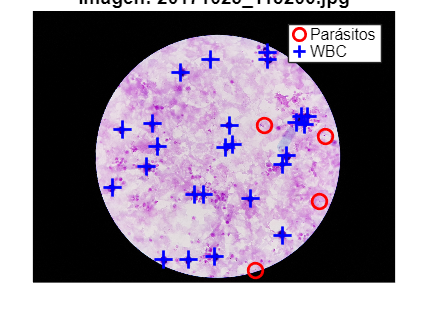

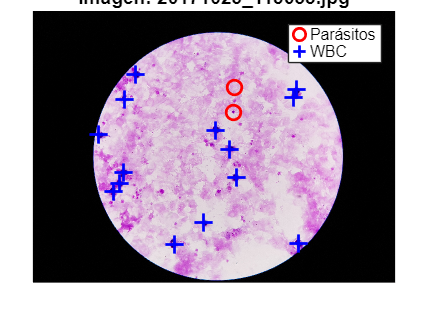

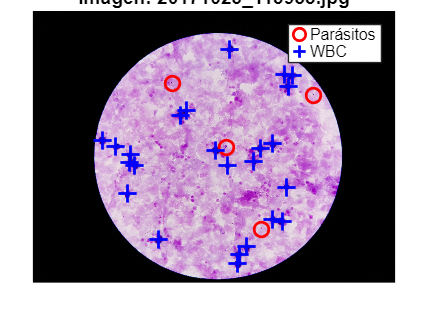

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF1N_1522', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasite'), :);
    if ismember('Var8', datos.Properties.VariableNames) && ismember('Var9', datos.Properties.VariableNames)
    x_parasitos = (solo_parasitos.Var6 + solo_parasitos.Var8) / 2;
    y_parasitos = (solo_parasitos.Var7 + solo_parasitos.Var9) / 2;
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    leyenda_parasitos = true;
    else
    disp(['No se encontraron coordenadas de parásitos en la imagen: ', imageFiles(i).name]);
    leyenda_parasitos = false;
    end
    
    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    if leyenda_parasitos
    legend('Parásitos', 'WBC');
    else
    legend('WBC');
    end
    hold off;
end

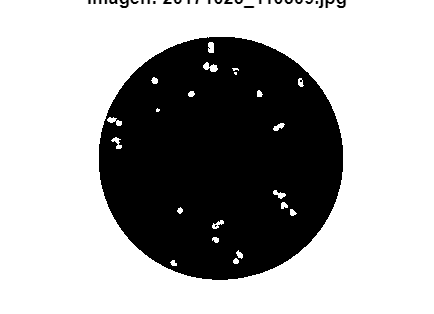

numero_de_wbc = 25

candidatos_a_wbc = 22

wbc_detectados = 18

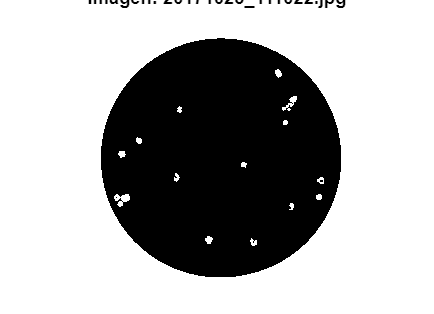

numero_de_wbc = 19

candidatos_a_wbc = 17

wbc_detectados = 16

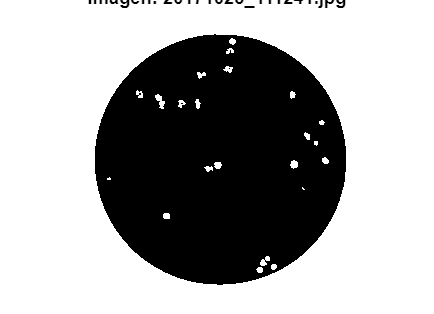

numero_de_wbc = 22

candidatos_a_wbc = 24

wbc_detectados = 21

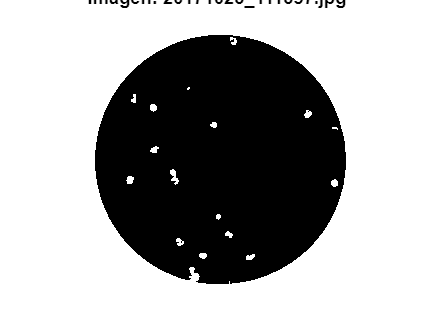

numero_de_wbc = 17

candidatos_a_wbc = 17

wbc_detectados = 14

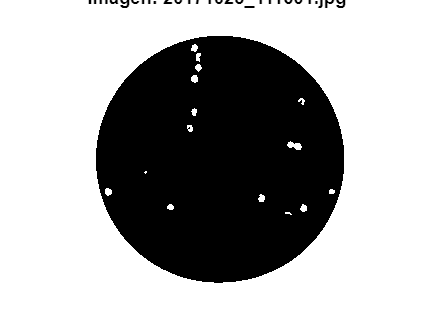

numero_de_wbc = 14

candidatos_a_wbc = 16

wbc_detectados = 13

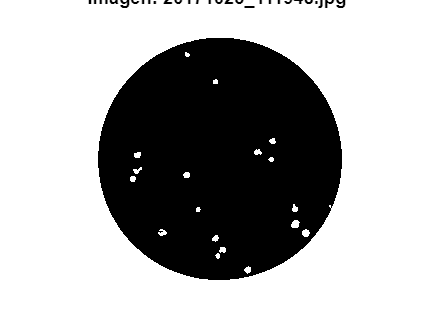

numero_de_wbc = 18

candidatos_a_wbc = 20

wbc_detectados = 18

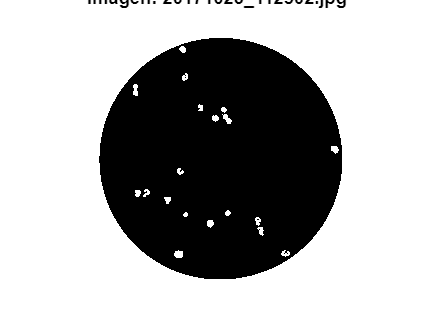

numero_de_wbc = 21

candidatos_a_wbc = 20

wbc_detectados = 19

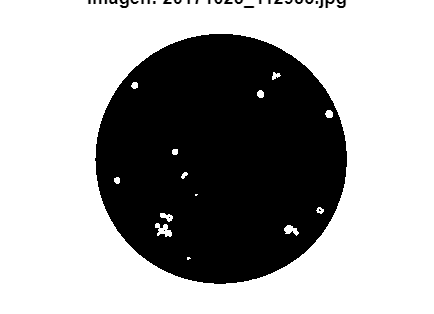

numero_de_wbc = 16

candidatos_a_wbc = 15

wbc_detectados = 12

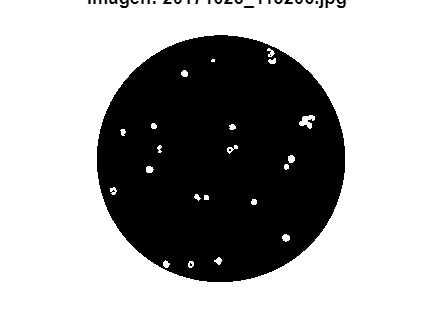

numero_de_wbc = 25

candidatos_a_wbc = 23

wbc_detectados = 22

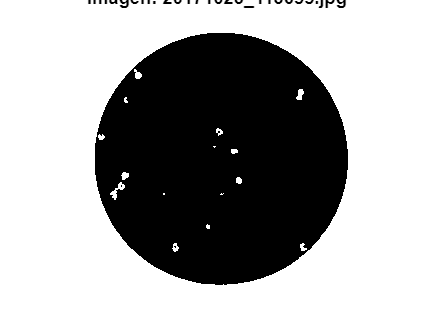

numero_de_wbc = 14

candidatos_a_wbc = 18

wbc_detectados = 13

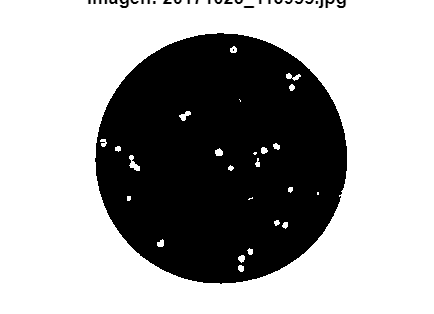

numero_de_wbc = 24

candidatos_a_wbc = 27

wbc_detectados = 22

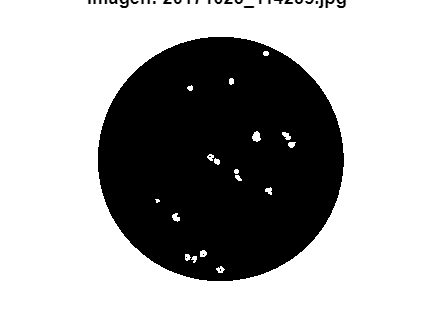

numero_de_wbc = 16

candidatos_a_wbc = 18

wbc_detectados = 16

total_wbc_reales = 0;
total_candidatos = 0;
total_wbc_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=rgb2gray(I);
    
    % Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);
 
    % Aplicar imsegkmeans directamente (necesita uint8 o single)
    [L, cluster_centers] = imsegkmeans(I_sinruido, 3);

    mean_intensity = zeros(3,1);
    for a = 1:3
        mean_intensity(a) = mean(I_sinruido(L==a), 'all');
    end
    [~, idx_darkest] = min(mean_intensity);
    dark_points_mask = L == idx_darkest;
    
    % === Filtrar WBC (regiones grandes) ===
    globulos_blancos = bwareaopen(dark_points_mask, 500);
  
    % Visualiza la máscara final
    figure;
    imshow(globulos_blancos);hold on;
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF1N_1522', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;

    % ============Verificar el modelo========
    
    % Extraer el numero de wbc
    tamano=size(solo_WBC);
    numero_de_wbc = tamano(1,1)
    n=8;
    % Candidatos a wbc
    CC_2 = bwconncomp(globulos_blancos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_wbc=tamano(1,1)

    % wbc detectados
    umbral_distancia = 50;
    wbc_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada wbc real
    for p = 1:length(x_wbc)
        centro_real = [x_wbc(p), y_wbc(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                wbc_detectados = wbc_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un wbc detectado más de una vez
            end
        end
    end
    % Mostrar wbc detectados
    wbc_detectados

    % Sumas de los wbc reales, candidatos y detectados 
    total_wbc_reales = total_wbc_reales + numero_de_wbc;
    total_candidatos = total_candidatos + candidatos_a_wbc;
    total_wbc_detectados = total_wbc_detectados + wbc_detectados;
end


% Analizar modelo con estos resultados
total_wbc_reales

total_wbc_reales = 231

total_candidatos

total_candidatos = 237

total_wbc_detectados

total_wbc_detectados = 204


% Confusion matrix
TP=total_wbc_detectados;
FP=total_candidatos-total_wbc_detectados;
FN=total_wbc_reales-total_wbc_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 88.3117

precision=(TP/(TP+FP))*100

precision = 86.0759

## PARASITOS

### b) 3º Modelo K-means color

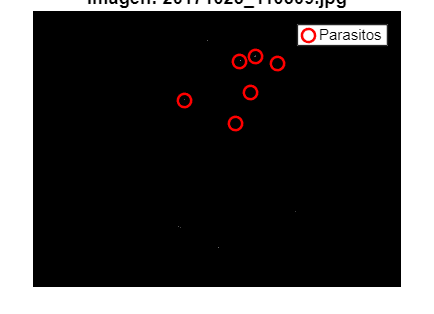

numero_de_parasitos = 6

candidatos_a_parasitos = 18

parasitos_detectados = 4

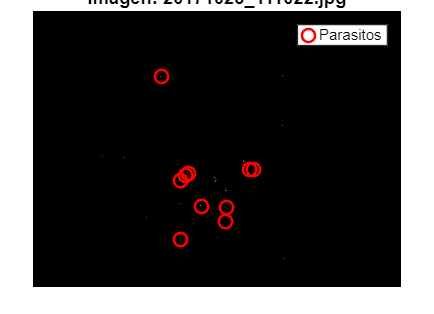

numero_de_parasitos = 10

candidatos_a_parasitos = 34

parasitos_detectados = 7

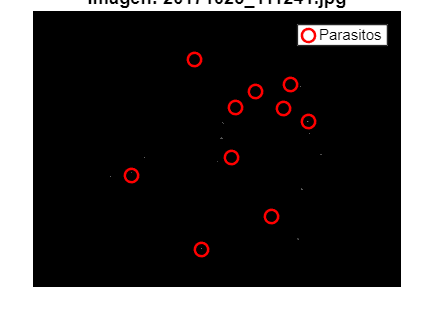

numero_de_parasitos = 10

candidatos_a_parasitos = 23

parasitos_detectados = 5

No se encontraron coordenadas de parásitos en la imagen: 20171023_111357.jpg


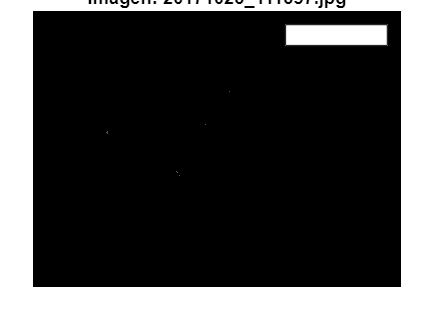

numero_de_parasitos = 0

candidatos_a_parasitos = 31

parasitos_detectados = 0

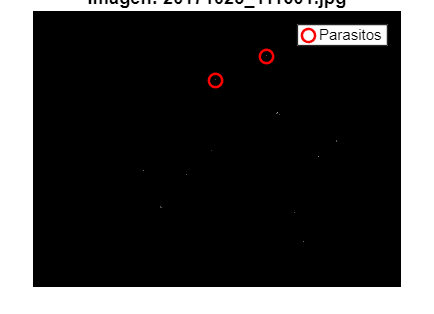

numero_de_parasitos = 2

candidatos_a_parasitos = 21

parasitos_detectados = 2

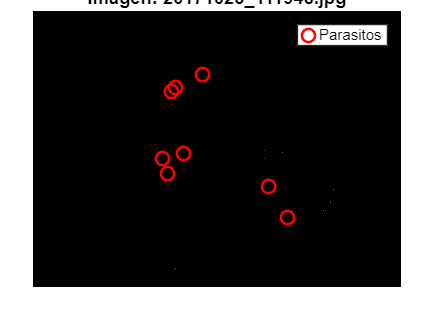

numero_de_parasitos = 8

candidatos_a_parasitos = 23

parasitos_detectados = 1

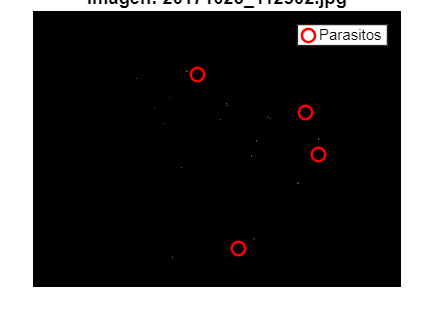

numero_de_parasitos = 4

candidatos_a_parasitos = 42

parasitos_detectados = 1

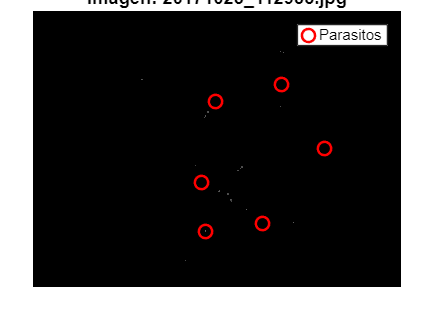

numero_de_parasitos = 6

candidatos_a_parasitos = 36

parasitos_detectados = 5

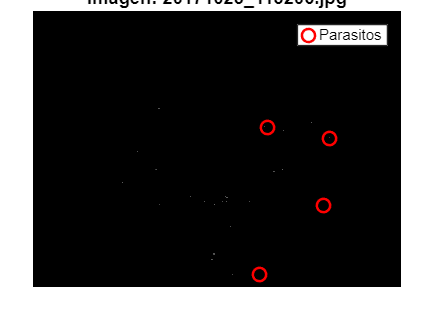

numero_de_parasitos = 4

candidatos_a_parasitos = 47

parasitos_detectados = 3

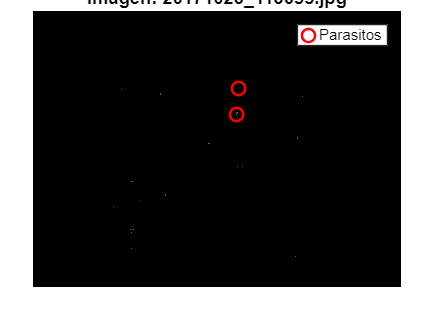

numero_de_parasitos = 2

candidatos_a_parasitos = 32

parasitos_detectados = 2

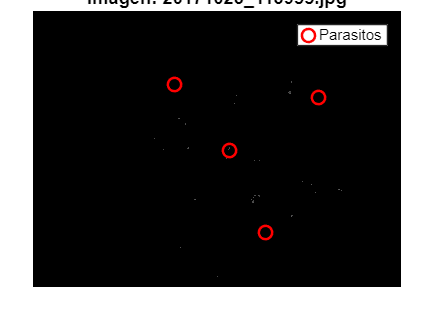

numero_de_parasitos = 4

candidatos_a_parasitos = 52

parasitos_detectados = 3

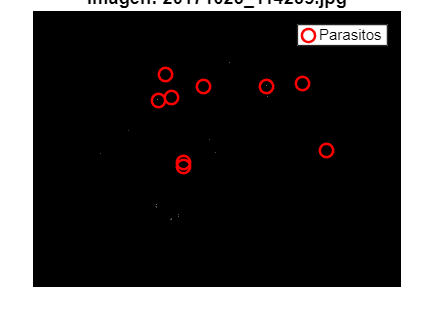

numero_de_parasitos = 9

candidatos_a_parasitos = 20

parasitos_detectados = 4

total_parasitos_reales = 0;
total_candidatos = 0;
total_parasitos_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=rgb2gray(I);
    
    % Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);
    
    % Aplicar imsegkmeans directamente (necesita uint8 o single)
    [L, cluster_centers] = imsegkmeans(I_sinruido, 3);

    mean_intensity = zeros(3,1);
    for c = 1:3
        mean_intensity(c) = mean(I_sinruido(L==c), 'all');
    end
    [~, idx_darkest] = min(mean_intensity);
    dark_points_mask = L == idx_darkest;
    
    % === Filtrar WBC (regiones grandes) ===
    WBC_mask = bwareaopen(dark_points_mask, 500);
    parasite_candidate_mask = dark_points_mask & ~WBC_mask;
    
    % === Procesamiento morfológico ===
    se = strel('disk', 2);
    dilated = imdilate(parasite_candidate_mask, se);
    filled = imfill(dilated, 'holes');
    opened = imopen(filled, strel('disk',1));
    
    % === Preparar imagen para imfindcircles ===
    mascara_parasitos = im2double(I_gray);
    mascara_parasitos(~opened) = 0;  % Fondo negro
    
    % % === Detección de círculos (parásitos) ===
    % [centers, radii] = imfindcircles(mascara_parasitos, [1 4], ...
    %     'ObjectPolarity','dark', 'Sensitivity', 0.93, 'EdgeThreshold', 0.1);
    % 
    % % === Mostrar resultados ===
    % figure; imshow(I); hold on;
    % viscircles(centers, radii, 'Color','r');

    % Visualiza la máscara final
    figure;
    imshow(mascara_parasitos);hold on;
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF1N_1522', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasite'), :);
    if ismember('Var8', datos.Properties.VariableNames) && ismember('Var9', datos.Properties.VariableNames)
    x_parasitos = (solo_parasitos.Var6 + solo_parasitos.Var8) / 2;
    y_parasitos = (solo_parasitos.Var7 + solo_parasitos.Var9) / 2;
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    leyenda_parasitos = true;
    else
    disp(['No se encontraron coordenadas de parásitos en la imagen: ', imageFiles(i).name]);
    leyenda_parasitos = false;
    end
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    if leyenda_parasitos
    legend('Parasitos');
    else
    legend('No parasitos');
    end
    hold off;

    % ============Verificar el modelo========
    
    % Extraer el numero de parasitos
    tamano=size(solo_parasitos);
    numero_de_parasitos = tamano(1,1)
    n=8;
    % Candidatos a parasitos
    CC_2 = bwconncomp(mascara_parasitos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_parasitos=tamano(1,1)

    % Parasitos detectados
    umbral_distancia = 50;
    parasitos_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada parásito real
    for p = 1:length(x_parasitos)
        centro_real = [x_parasitos(p), y_parasitos(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                parasitos_detectados = parasitos_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un parásito detectado más de una vez
            end
        end
    end
    % Mostrar parasitos detectados
    parasitos_detectados

    % Sumas de los parasitos reales, candidatos y detectados 
    total_parasitos_reales = total_parasitos_reales + numero_de_parasitos;
    total_candidatos = total_candidatos + candidatos_a_parasitos;
    total_parasitos_detectados = total_parasitos_detectados + parasitos_detectados;
end


% Ananlizar modelo con estos resultados
total_parasitos_reales

total_parasitos_reales = 65

total_candidatos

total_candidatos = 379

total_parasitos_detectados

total_parasitos_detectados = 37


% Confusion matrix
TP=total_parasitos_detectados;
FP=total_candidatos-total_parasitos_detectados;
FN=total_parasitos_reales-total_parasitos_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 56.9231

precision=(TP/(TP+FP))*100

precision = 9.7625